## FA3 strain

modelName = 'FA3NFB';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')
set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Manual Switch3",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','2') % FA3NFB model

p = sdo.getParameterFromModel(modelName,{'IPTG','addTime','arabi'});

% IPTG
p(1).Value = 100;
p(1).Minimum = 0;
p(1).Maximum = 1000;
p(1).Scale = 1000;
p(1).Free = 1;

% Arabinose adding time
p(2).Value = 0;
p(2).Minimum = 0;
p(2).Maximum = 25;
p(2).Scale = 25;
p(2).Free = 1;

% Arabinose concentration
p(3).Value = 0.5;
p(3).Minimum = 0;
p(3).Maximum = 1;
p(3).Scale = 1;
p(3).Free = 1;

options = sdo.OptimizeOptions;
options.Method = 'fmincon';

Exp = sdo.Experiment(modelName);
Exp = setEstimatedValues(Exp,p);

FFASignal = Simulink.SimulationData.Signal;
FFASignal.Name = 'Fatty acid';
FFASignal.BlockPath = modelName + "/GainFA";
FFASignal.PortType = 'outport';
FFASignal.PortIndex = 1;
FFASignal.Values = timeseries((1:25)',(1:25)'); % What does this mean?

Exp.OutputData = FFASignal; % add the signal object to the experiment

Simulator = createSimulator(Exp);
estFcn = @(p) optInputObjective(p,Simulator,Exp);

val = optInputObjective(p,Simulator,Exp);
val.F

ans = -1.1282

tic
[optInput,optInputInfo] = sdo.optimize(estFcn,p,options)


 最適化開始時間 08-Nov-2023 21:58:29

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      6     -1.12823            0
    1     15     -1.16689            0        0.703         3.67
    2     22     -1.52545            0        0.459         0.75
    3     28     -1.56434            0        0.465         1.58
    4     36     -1.73405            0        0.289         2.42
    5     42     -1.82752            0        0.113         1.56
    6     48     -1.96887            0        0.128         0.82
    7     55     -1.98056            0        0.368         3.77
    8     61     -2.06435            0        0.227         2.63
    9     67     -2.12826            0       0.0453        0.673
   10     74     -2.15355            0        0.104         1.74
   11     80     -2.17212            0       0.0397        0.333
   12     86      -2.1806            0       0.0224        0.133
   13     92   

optInputInfo = フィールドをもつ struct :
               F: -2.1839
       Gradients: [1×1 struct]
        exitflag: 2
      iterations: 14
    SolverOutput: [1×1 struct]
           Stats: [1×1 struct]


toc

経過時間は 92.251675 秒です。


maxFFA_FA3NFB = -optInputInfo.SolverOutput.fval;

spv_length = 26;
setPointValuesIPTG = logspace(0,3,spv_length); % 1-1000 uM IPTG
setPointValuesAddTime = linspace(0,25,spv_length); % 0-25 h arabinose adding time

k = 1;
for i = 1:1:spv_length
    for j = 1:1:spv_length
        in(k) = Simulink.SimulationInput(modelName);
        in(k) = in(k).setBlockParameter(modelName + "/To optimize input",...
        'Value',num2str(setPointValuesIPTG(i)));
        in(k) = in(k).setBlockParameter(modelName + "/Arabinose",...
            'Time',num2str(setPointValuesAddTime(j)));
        k = k + 1;
    end
end

out_FA3NFB = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[08-Nov-2023 22:06:39] シミュレーションの実行中...
[08-Nov-2023 22:06:42] シミュレーション実行 1/676 が完了
[08-Nov-2023 22:06:43] シミュレーション実行 2/676 が完了
[08-Nov-2023 22:06:45] シミュレーション実行 3/676 が完了
[08-Nov-2023 22:06:46] シミュレーション実行 4/676 が完了
[08-Nov-2023 22:06:47] シミュレーション実行 5/676 が完了
[08-Nov-2023 22:06:48] シミュレーション実行 6/676 が完了
[08-Nov-2023 22:06:49] シミュレーション実行 7/676 が完了
[08-Nov-2023 22:06:51] シミュレーション実行 8/676 が完了
[08-Nov-2023 22:06:52] シミュレーション実行 9/676 が完了
[08-Nov-2023 22:06:53] シミュレーション実行 10/676 が完了
[08-Nov-2023 22:06:54] シミュレーション実行 11/676 が完了
[08-Nov-2023 22:06:55] シミュレーション実行 12/676 が完了
[08-Nov-2023 22:06:56] シミュレーション実行 13/676 が完了
[08-Nov-2023 22:06:57] シミュレーション実行 14/676 が完了
[08-Nov-2023 22:06:58] シミュレーション実行 15/676 が完了
[08-Nov-2023 22:06:59] シミュレーション実行 16/676 が完了
[08-Nov-2023 22:07:00] シミュレーション実行 17/676 が完了
[08-Nov-2023 22:07:01] シミュレーション実行 18/676 が完了
[08-Nov-2023 22:07:02] シミュレーション実行 19/676 が完了
[08-Nov-2023 22:07:03] シミュレーション実行 20/676 が完了
[08-Nov-2023 22:07:05] シミュレーション実行 21/676 が完了
[08-Nov-2023 22:07:06] シミ

out_FA3NFB = 1x676 Simulink.SimulationOutput 配列



FFAfinal_FA3NFB = zeros(spv_length^2,1);
for simIdx = 1:spv_length^2
    FFAfinal_FA3NFB(simIdx,1) = out_FA3NFB(simIdx).logsout{1}.Values.Data(end);
end

FFAfinal_FA3NFB = reshape(FFAfinal_FA3NFB,[spv_length,spv_length]);
[X,Y] = meshgrid(logspace(0,3,spv_length),linspace(0,25,spv_length));

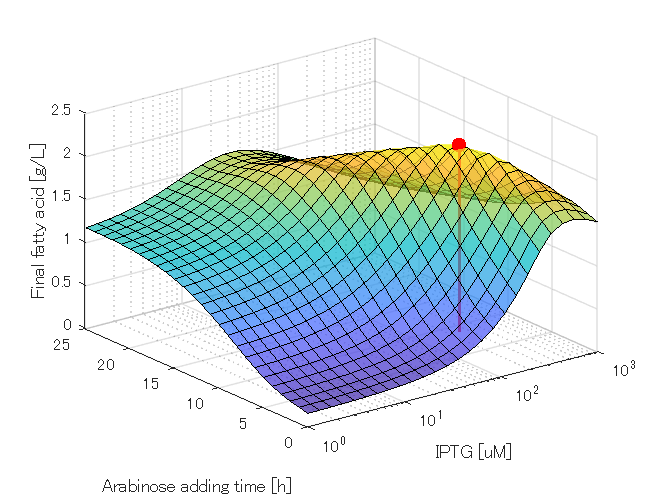

figure('Position', [100 100 480 360]);
surf(X,Y,FFAfinal_FA3NFB);
xlim([1 1000])
ylim([0 25])
zlim([0 2.5])
xlabel('IPTG [uM]')
ylabel('Arabinose adding time [h]')
zlabel('Final fatty acid [g/L]')
set(gca,'xscale','log')
alpha(0.7)
% clim([0 2.5])
hold on
stem3(optInput(1).Value,optInput(2).Value,maxFFA_FA3NFB,'ro','MarkerFaceColor','red','LineWidth',2)
hold off

sdo.setValueInModel(modelName,optInput);